# **Tutorial 11**: the 4 bar mechanism  ( $\approx 3\;mn$ run)

*by D. Alazard and F. Sanfedino - ISAE-SUPAERO*

## 1. Description

The objective of this tutorial is to illustrate on the well-known 4 bar mechanism how it is possible to model closed kinematic chains of rigid or flexible bodies with the `SDTlib`. Let us consider the 4 bar mechanism depicted in the following Figure charcaterized by  3 uniform bars (the $4$-th bar being the inertial frame or ground) in the $\mathbf x, \mathbf y$-plane and  4 revolute joints around $\mathbf z$-axis. Let us consider the particular case where the 4 bars shape a parallelogram.

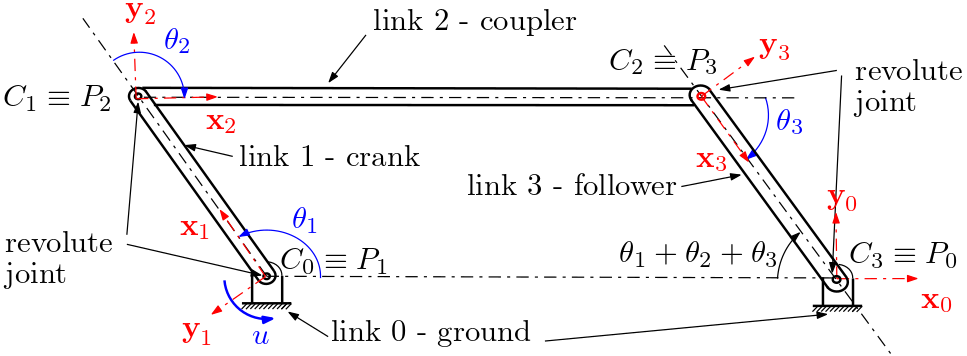

Indeed, as it is mentionned in the [***introduction***](matlab:open('../Tutorial1/tutorial1.html')) (tutorial 1), such a closed kinematic chain have some non-linear loop closure constraints $\mathbf g(\mathbf \theta,\mathbf x_f)=\mathbf 0$ which are not solved in the `SDTlib. `

$\mathbf \theta=[\theta_1,\;\theta_2,\;\theta_3]^T$ is the vector of the 3 d.o.fs but the 2 constraints (the points $C_3$ and $P_0$ must coincide at any time):

$l_1\cos{\theta_1}+l_2\cos{(\theta_1+\theta_2)}+l_3\cos{(\theta_1+\theta_2+\theta_3)}=l_0$,


$$l_1 \sin{\theta_1}+l_2 \sin{(\theta_1+\theta_2)}+l_3\sin{(\theta_1+\theta_2+\theta_3)}=0$$


(where $l_i$ is the length of the link $i$) reduce to 1 the number of independent d.o.f. 

In the case where $l_1=l_3$ and $l_0=l_2$ (parralelogram), these constraints can be easily solved:

$\theta_1=\theta,\quad \theta_2=-\theta,\quad \theta_3=\theta-\pi$.

Thus, in this particular case where the loop closure constraints are solved, it is possible to build the dynamic model of this mechanism fully parameterized acconding to $\theta$.

**Numerical application:  **all the links are made of aluminium beams with a square cross section of $1\,cm$ side. $l_1=l_3=0.75\,m$ and $l_0=l_2=1\,m$.

In the next sections the objective is to compute the dynamic model from $u\,(Nm)$, the torque applied by an actuator inside the revolute joint between links # 0 and 1 at the point $P_1$ to:

- the angular accelerations $\ddot\theta_1$, $\ddot\theta_2$ and $\ddot\theta_3$. Then one can check that the loop closure constraints are met at the acceleration level. One can aslo compute the apparent inertia $I_{z,P_1}\;(Kg\,m^2)$seen from the actuator at point $P_1$ i.e. the inverse of the DCgain of the transfer $\frac{\ddot\theta_1}{u}(\mathrm s,\theta)$,

- the axial and radial forces $F_{x_3,C_3}$, $F_{y_3,C_3}$ applied to the link 3 at point $C_3$ (along $\mathbf x_3$-axis and $\mathbf y_3$ axis, respectively),

in the case where the beams are rigid (section 2) and in the case where the beams are flexible (section 3)

In section 4 and section 5, the problem is reconsidered when the link # 0 is also a beam and when the system is free to move in the 3D space.

## 2. Rigid case

The simulink model is described in the SIMULINK file `FourRigidBarsAug.slx` (see following Figure):

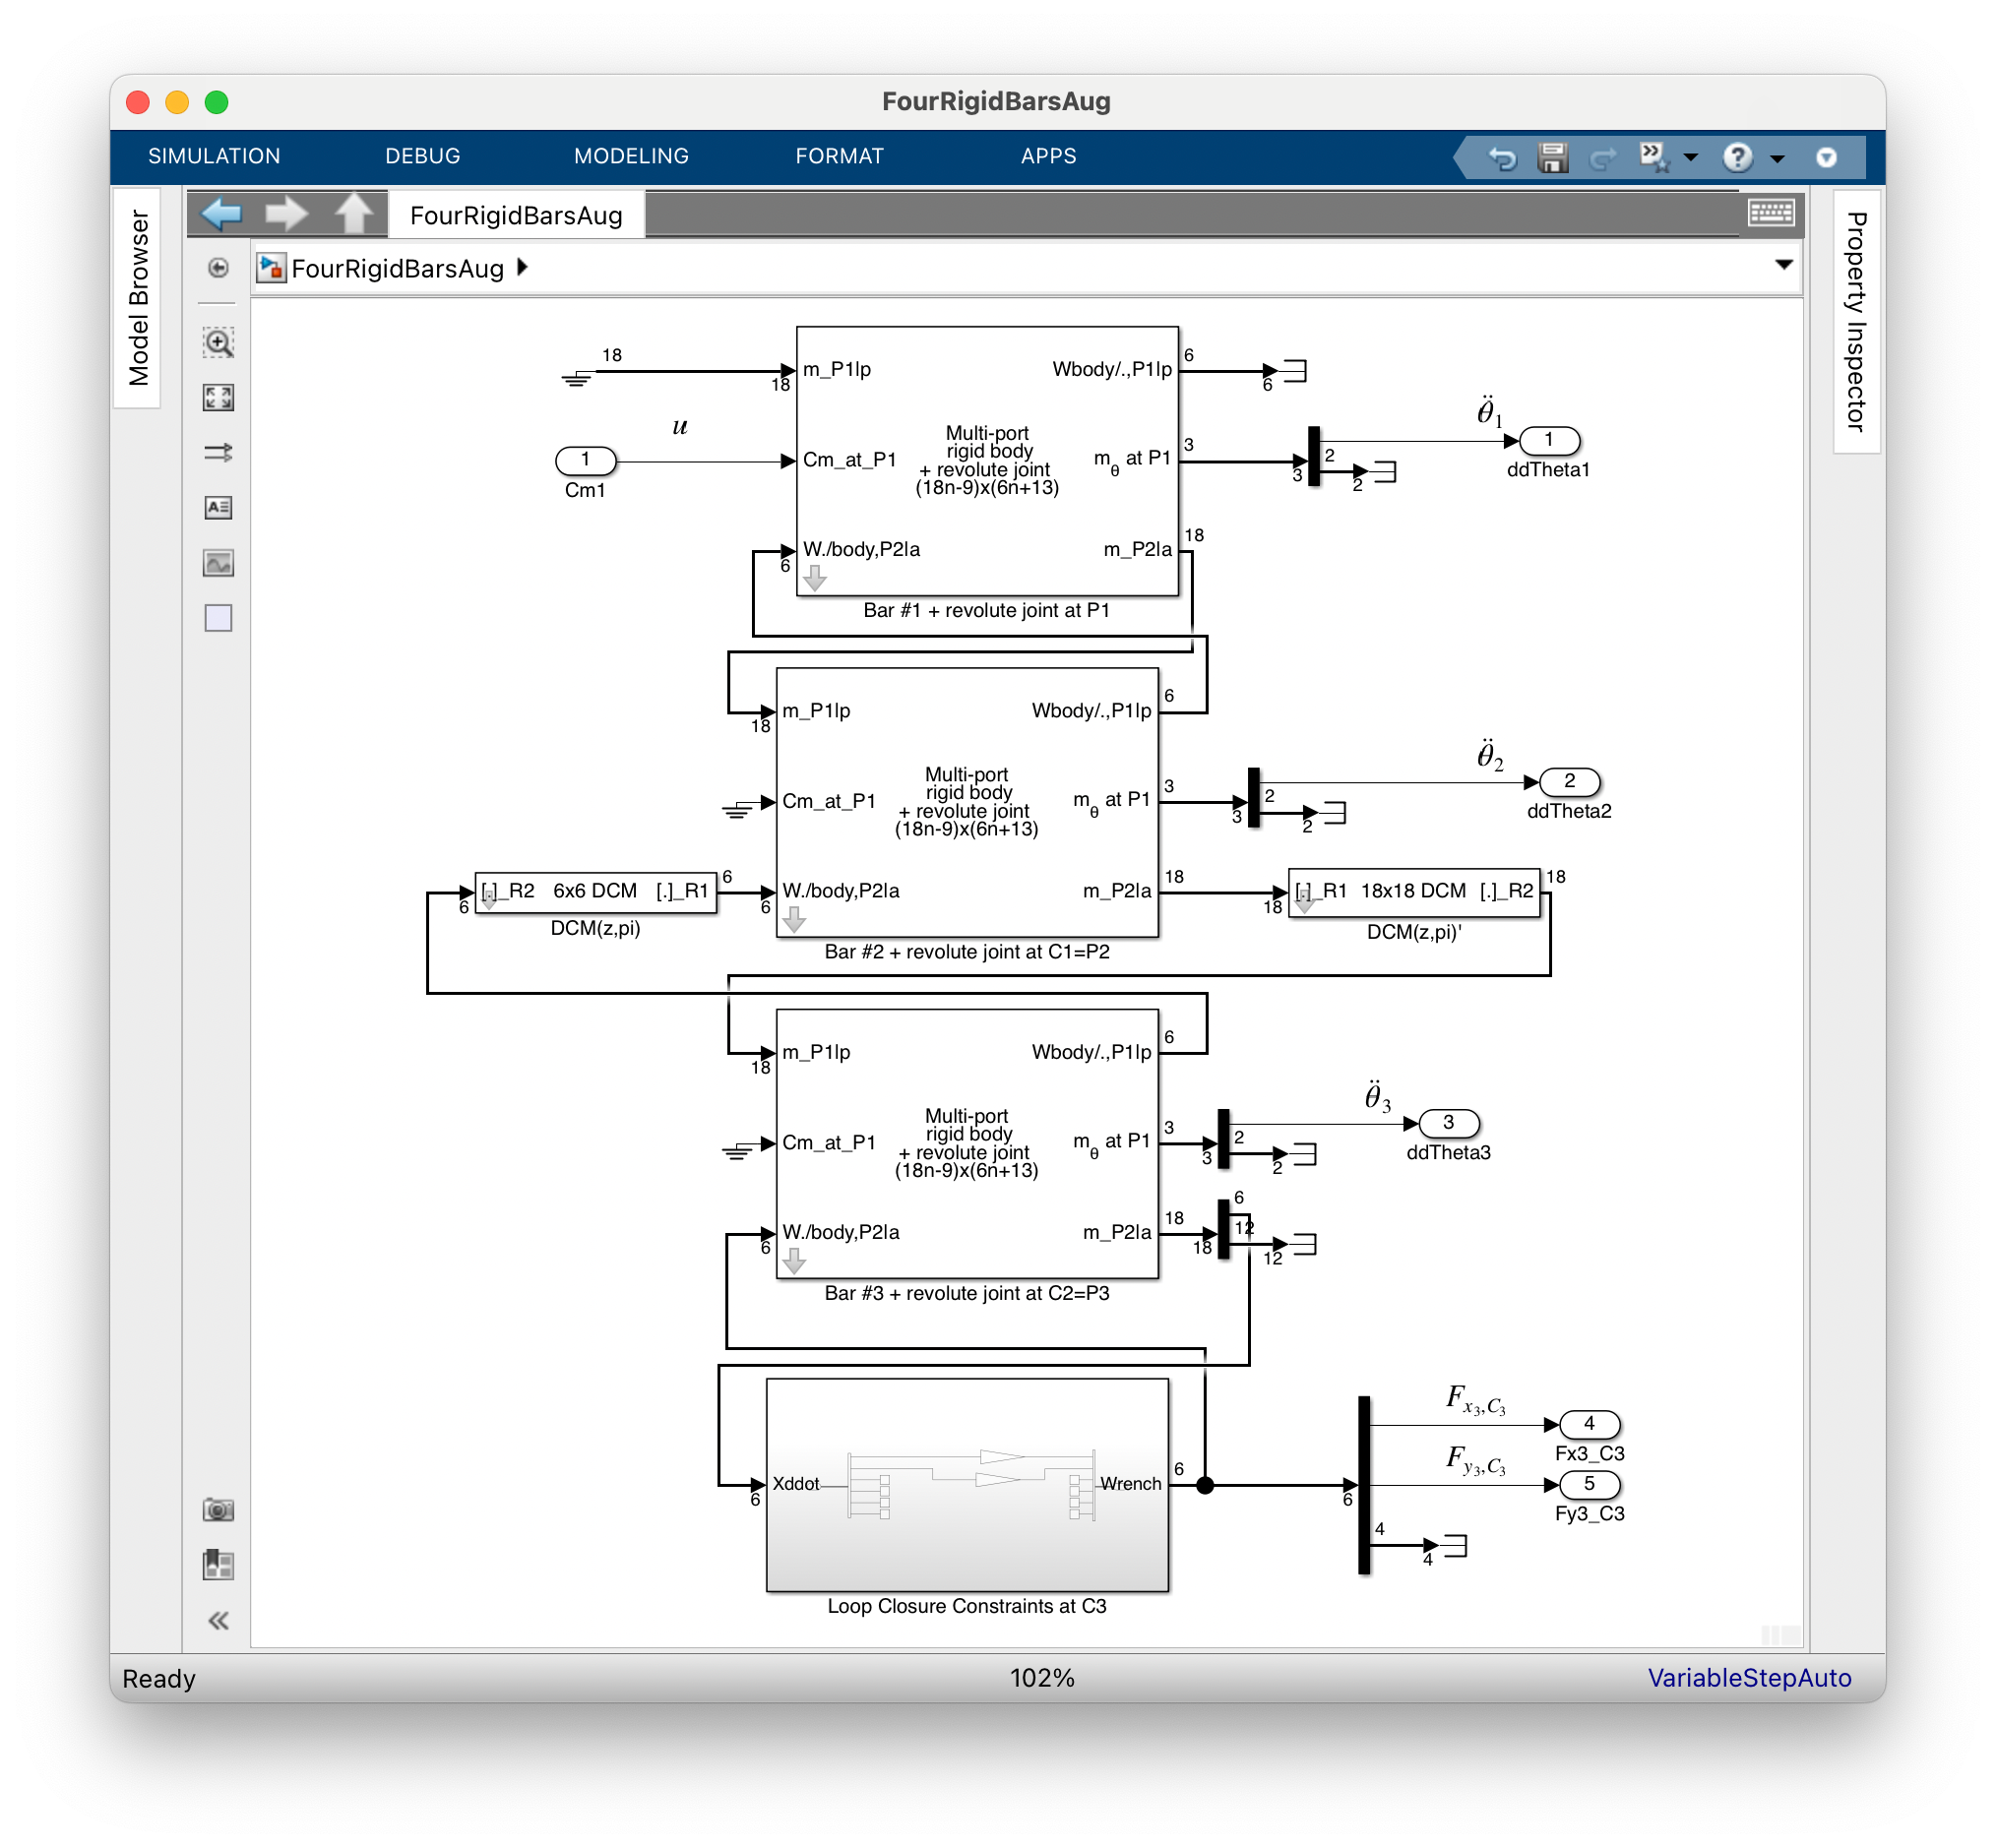

This SIMULINK model involves 

- 3 blocks `Multi-port rigid body + revolute joint` from the `Predefined subsystems` sub-library, associated to the 3 links # 1, 2 and 3. Note that in the dialog box of these blocks, the field `Angular configuration (rad)` does not support operations: thus the rotation $\theta_2=-\theta$ is specified as a rotation of $+\theta$ around $-\mathbf z$-axis. Note also that only accelerations are considered on the outputs and to close the kinematic chain at point $C_3$,

- DCMs for the rotation of $\pi$ around $\mathbf z$-axis (involved in $\theta_3$).

- and the` Loop-cloure Constraints in C3` block required to close the kinematic loop at the point $C_3$. The simplest way to close the loop is to specify that the point $C_3$ of the link # 3 is loaded by a very big mass ( $10^{6}\,Kg$ ) operating along the $\mathbf x$ and $\mathbf y$-axes. The detail of this block is given below:

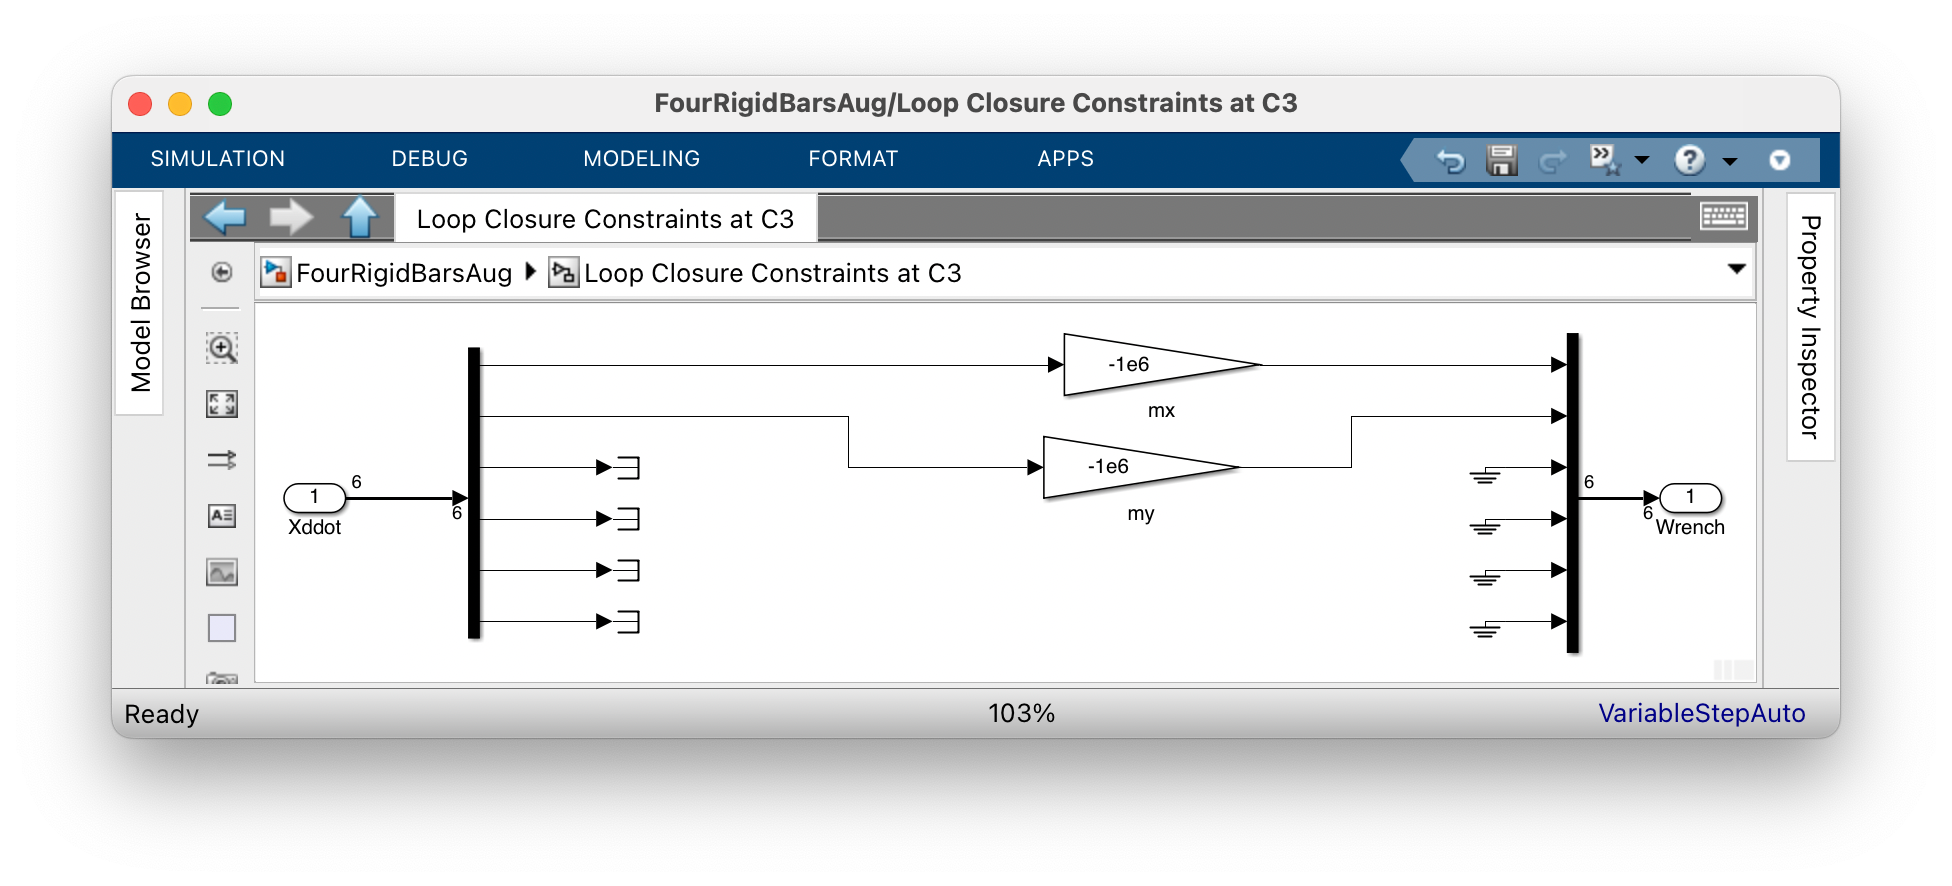

The data of the model:

% General data: aluminium beams with square cross section: thickness 1 cm
h=0.01;              % side of the square cross section (m)
rho=2700;            % mass density (Kg/m^3)
% Bar # 1:
l1=0.75;             % length (m)
m1=rho*l1*h^2;       % mass  (Kg)
I1_G=diag([m1*h^2/6 m1/12*(h^2+l1^2) m1/12*(h^2+l1^2)]); % Inertia matrix at CdG (Kg.m^2)
% Bar # 2:
l2=1;
m2=rho*l2*h^2;
I2_G=diag([m2*h^2/6 m2/12*(h^2+l2^2) m2/12*(h^2+l2^2)]);
% Bar # 3:
l2=1;
m2=rho*l2*h^2;
I2_G=diag([m2*h^2/6 m2/12*(h^2+l2^2) m2/12*(h^2+l2^2)]);
% Bar # 3:
l3=l1;
m3=rho*l3*h^2;
I3_G=diag([m3*h^2/6 m3/12*(h^2+l3^2) m3/12*(h^2+l3^2)]);
% Bar # 4 is the inertial frame

The geometric configuration $\theta$ is varying between $0$ and $\pi$(due to symmetry). 

Theta=ureal('theta',pi/2,'Range',[0 pi]);

The SIMULINK model:

FourRigidBarsAug
Gu=ulinearize('FourRigidBarsAug');
Gu=sminreal(Gu)

Gu =

  Uncertain continuous-time state-space model with 5 outputs, 1 inputs, 0 states.
  The model uncertainty consists of the following blocks:
    tan_theta_div4: Uncertain real, nominal = 0.414, range = [0,1], 16 occurrences

Type "Gu.NominalValue" to see the nominal value, "get(Gu)" to see all properties, and "Gu.Uncertainty" to interact with the uncertain elements.



This $5\times 1$model is static. Indeed since only acceleration are considered on the ouputs, the rigid modes are reduced.

Gu0=simplify(Gu.d,'full')

Gu0 =

  Uncertain matrix with 5 rows and 1 columns.
  The uncertainty consists of the following blocks:
    tan_theta_div4: Uncertain real, nominal = 0.414, range = [0,1], 16 occurrences

Type "Gu0.NominalValue" to see the nominal value, "get(Gu0)" to see all properties, and "Gu0.Uncertainty" to interact with the uncertain elements.



Then one can transform it into a matrix, scheduled according to $\theta$ varying by a step of $1\,deg$ between $1\,deg$ and $179\,deg$. Note that $\theta=0\,deg$ and $\theta=180\,deg$ are singular configurations.

theta=[1:1:179]*pi/180;
clear sysLPV
for ii = 1:length(theta),
     sig4=tan(theta(ii)/4);
     sysLPV(:,:,ii) = usubs(Gu0,'tan_theta_div4',sig4);
end

Then one can plot the apparent inertia $I_{z,P_1}\;(Kg\,m^2)$  and the gains between $u$ and the 2 outputs $F_{x_3,C_3}$, $F_{y_3,C_3} \,(m^{-1})$ as functions of $\theta$.

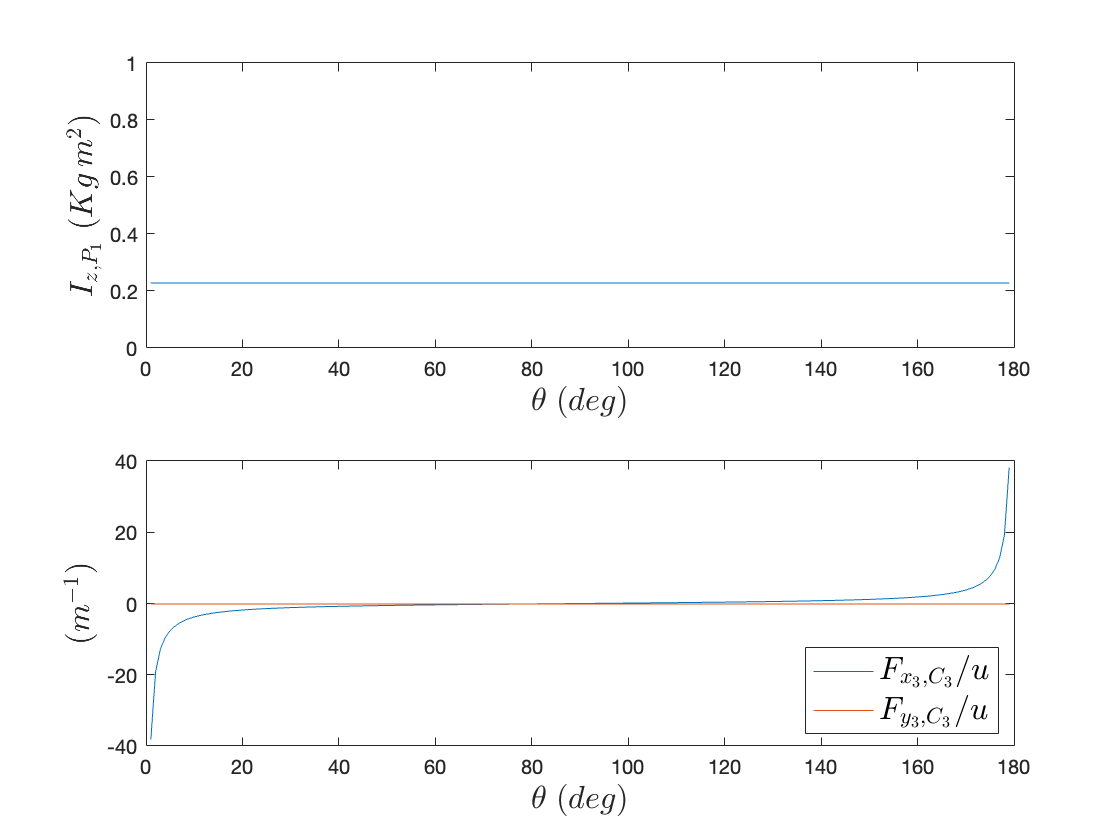

figure
subplot(2,1,1)
plot(theta*180/pi,1./squeeze(sysLPV(1,1,:)))
xlabel('$\theta\;(deg)$','Interpreter','Latex','Fontsize',16)
ylabel('$I_{z,P_1}\;(Kg\,m^2)$','Interpreter','Latex','Fontsize',16)
set(gca,'Ylim',[0 1])
subplot(2,1,2)
plot(theta*180/pi,squeeze(sysLPV(4:5,1,:)))
xlabel('$\theta\;(deg)$','Interpreter','Latex','Fontsize',16)
ylabel('$(m^{-1})$','Interpreter','Latex','Fontsize',16)
legend('$F_{x_3,C_3}/u$','$F_{y_3,C_3}/u$','Interpreter','Latex',...
       'Fontsize',16,'Location','southeast')

It is interesting to note that the apparent inertia at point $P_1$is constant for any value of $\theta$ i.e; the shape of the parralelogram). It is also true for the radial force $F_{y_3,C_3}$.

Finally one can check that the accelerations $\ddot\theta_1$, $\ddot\theta_2$ and $\ddot\theta_3$ meet the loop closure constraints for any value of $\theta$:

sysLPV(:,:,[10 45 90 135 170])

ans = ans(:,:,1) =

    4.3895
    4.3895
    4.3895
   -3.7808
   -0.1111


ans(:,:,2) =

    4.3895
    4.3895
    4.3895
   -0.6667
   -0.1111


ans(:,:,3) =

    4.3895
    4.3895
    4.3895
         0
   -0.1111


ans(:,:,4) =

    4.3895
    4.3895
    4.3895
    0.6667
   -0.1111


ans(:,:,5) =

    4.3895
    4.3895
    4.3895
    3.7808
   -0.1111


Indeed the first 3 conponents are always equal: all the revolute joint must have the same angular acceleration to meet the closure constraints.

## 3. Flexible case

When the links are considered flexible, it possible to specify 2 independent accelerations twists at 2 different points (see also the section 1.4 of [***tutorial 5***](matlab:open('../Tutorial5/tutorial5.html'))). Thus it is possible to meet the closure constraints at the acceleration level with the internal flexible states ( $\mathbf x_f$) of the system. 

For that, we need to apply the channel inversion function `invio` to the TITOP model of the flexible link where the loop is closed, here the link # 3 at point $C_3$. **Note also that these channel operations are performed on TITOP model of flexible body where the motion vectors are restricted to the 6 acceleration components.** Indeed, the position and the velocity at 2 different points of a flexible structure, when they are on the inputs of the model due to channel inversions, cannot be independent of the internal deflection positions and rates (internal state variables) and thus are not considered.

The matlab function used to compute the TITOP model of a flexible beam in the blocks `TITOP flexible beam` and `TITOP flexible beam + revolute joint` is the function `TwoPOrtBeamFull.`m (in the `SDTfct/bib_SDT` sub-directory):

help TwoPortBeamFull

  M=TwoPortBeamFull(ro,s,l,e,g,iz,iy,xi) computes the 2 input/output
  model M (12x12) of a uniform beam characterized by:
    * mass density: ro  (Kg/m^3),
    * section: s (m^2),
    * lenght: l (m),
    * Young modulus: e (Pascal or N/m^2),
    * shear modulus: g (Pascal or N/m^2),
    * second moment of area w.r.t z axis: iz (m^4),
    * second moment of area w.r.t y axis: iy (m^4),
    * xi: arbitrary damping ratio for all flexible modes.
           ^ y(x)
           |
           |
           x=======================x---------> x
          /P(x=0)                 C(x=l)
         /
        z
 
    The 12 inputs of M are:
       * the 6 components of the external force/torque vector applied
         to the beam at point C (in the frame (P,x,y,z)),
       * the 6 components of the linear/angular acceleration vector at
         point P (in the frame (P,x,y,z)).
    The 12 outputs of M are:
       * the 6 components of the linear/angular acceleration vector at
        

Then one can compute the TITOP model $[\mathbf{M}_{P_3,C_3}^{\mathcal{L}_3}]_{\mathcal R_3}(\mathrm s)$ of the link # 3 directly from the mechanical parameters:

S=h^2;          % beam cross seectio (m^2)
E=70e9;         % Young module (N/m^2)
ni=0.35;        % Poison coefficient
GG=E/(2*(1+ni));% Shear modulys (N/m^2)
Iz=h^4/12;      % second mooment of aera arount z-axis
Iy=Iz;          % second mooment of aera arount Y-axis
xi=0.001;       % common damping ratio
% TITOP model of the bar # 3
Bar3=TwoPortBeamFull(rho,S,l3,E,GG,Iz,Iy,xi);

This $12\times 12$  model corresponds to the following block diagram:

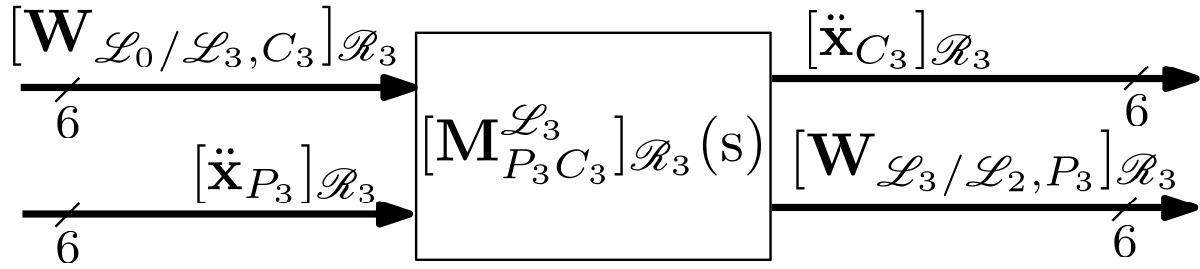

The inversion of the channels # 1,2,3,4,5 and 12 allows to specify that:

- **channels 1 to 5:** the first 5 components of the acceleration twist $\ddot\mathbf x_{C_3}$ at point $C_3$ are imposed. These 5 inputs will be set to $0$ in this application to meet the closure constraints. The forces $F_{x_3,C_3}$, $F_{y_3,C_3}$ to be analyzed corresponds to the outputs # 1 and 2,

- **channel 6**: the input # 6 is the torque applied inside the revolute joint between links 3 and $0$. It will be also set to 0. The output is the revolute joint acceleration 

- **channels 7 to 11**: the inputs # 7 to 11 are the first 5 components of the acceleration twist $\ddot\mathbf x_{P_3}$ imposed by the link # 2 at point $P_2$. The outputs are the first 5 component of the wrench $\mathbf{W}_{\mathcal{L}_3/\mathcal{L}_2,P_3}$ applied by the link # 3 to the link # 2 at point $P_3$ (interaction torque around $\mathbf z$-axis cannot be applied due to the revolute joint)

- **channel 12: **the input # 12 is the torque applied inside the revolute joint between links # 2 and 3. It will be also set to $0$. The output is the revolute joint acceleration $\ddot\theta_3$.

This model, named  $[\mathbf{M}_{P_3,C_3}^{\mathcal{L}_3}]^{-1_{[1:5,12]}}_{\mathcal R_3}(\mathrm s)$ can be represented by the following block-diagram:

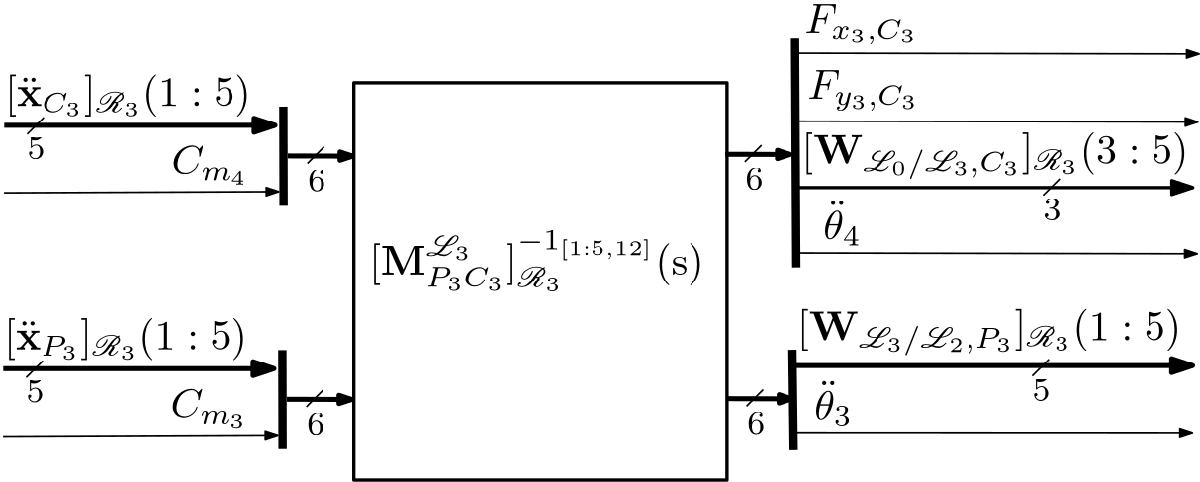

Then the SIMULINK model `FourFlexibleBarsAug.slx` involves this model with:

- 2 blocks `TITOP flexible beam + revolute joint`  for the links # 1 and 2,

- the DCMs associated to the frame rotation $\theta_3=\theta-\pi$.

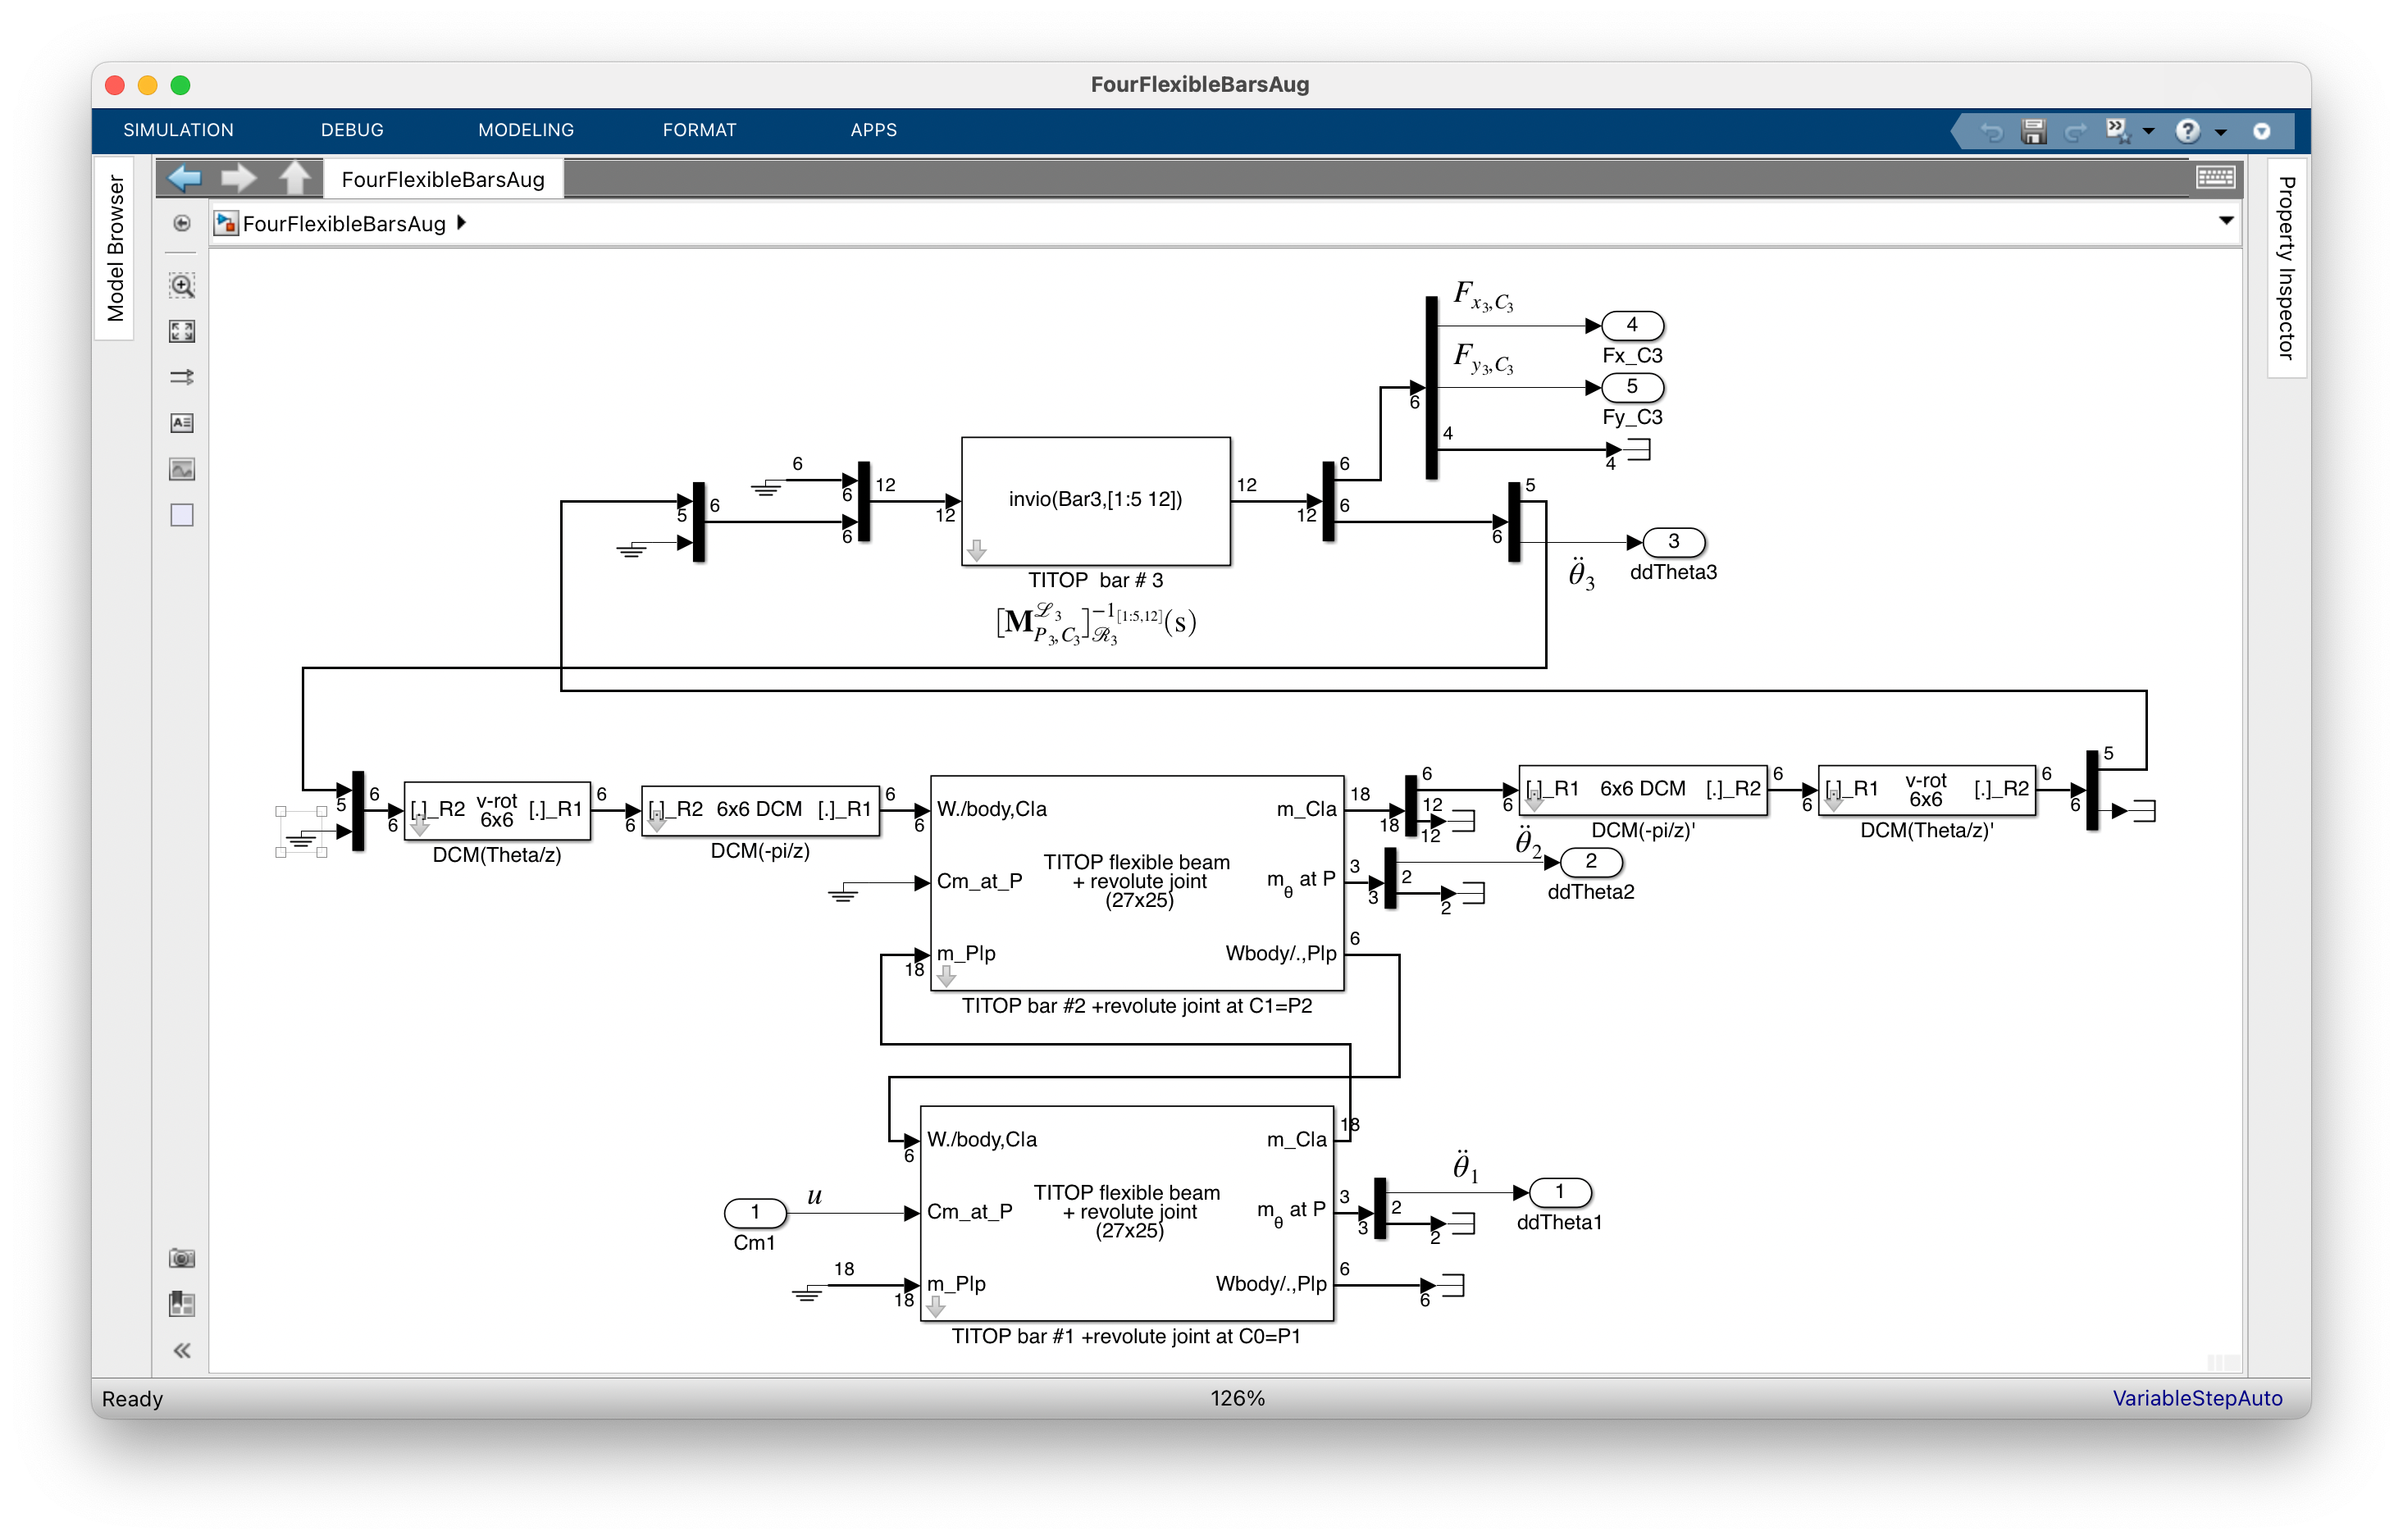

Let us consider the particular geometric configuration $\theta=\pi/4$ and compute the linear model with the `linmod` function:

Theta=pi/4;
FourFlexibleBarsAug
[a,b,c,d]=linmod('FourFlexibleBarsAug');
G=ss(a,b,c,d);
size(G)

State-space model with 5 outputs, 1 inputs, and 64 states.


damp(G)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  0.00e+00                -1.00e+00       0.00e+00              Inf    
  0.00e+00                -1.00e+00       0.00e+00              Inf    
  0.00e+00                -1.00e+00       0.00e+00              Inf    
  0.00e+00                -1.00e+00       0.00e+00              Inf    
 -2.21e-05 + 2.12e-05i     7.22e-01       3.07e-05         4.52e+04    
 -2.21e-05 - 2.12e-05i     7.22e-01       3.07e-05         4.52e+04    
  2.21e-05 + 2.12e-05i    -7.22e-01       3.07e-05        -4.52e+04    
  2.21e-05 - 2.12e-05i    -7.22e-01       3.07e-05        -4.52e+04    
 -4.47e-05                 1.00e+00       4.47e-05         2.24e+04    
  4.47e-05                -1.00e+00       4.47e-05        -2.24e

The order of the $5\times 1$ model `G` is $64$:

-  2 rigid modes of the revolute joints in the 2 blocks `TITOP flexible beam + revolute joint`

- and $10$ flexible modes by link since the 3D model of a flexible beam includes $4$ bending modes in the $(\mathbf x,\;\mathbf y)$-plane, $4$ bending modes in the $(\mathbf x,\;\mathbf z)$-plane, $1$ torsion mode aound the $\mathbf x$-axis of the beam and $1$ traction mode along its $\mathbf x$-axis. See also:

web  DocBeam.html -new

One can also check that $6$ poles are around $0$ due to the loop closure constraints.

These poles, the rigid modes and the out-of-$(\mathbf x,\;\mathbf y)$-plane flexible modes can be reduced using the fonction** minreal**:

Gxy=minreal(G);

34 states removed.


damp(Gxy)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -2.71e-01 + 1.66e+02i     1.64e-03       1.66e+02         3.68e+00    
 -2.71e-01 - 1.66e+02i     1.64e-03       1.66e+02         3.68e+00    
 -3.81e-01 + 2.58e+02i     1.48e-03       2.58e+02         2.62e+00    
 -3.81e-01 - 2.58e+02i     1.48e-03       2.58e+02         2.62e+00    
 -5.65e-01 + 3.10e+02i     1.82e-03       3.10e+02         1.77e+00    
 -5.65e-01 - 3.10e+02i     1.82e-03       3.10e+02         1.77e+00    
 -1.94e+00 + 5.82e+02i     3.34e-03       5.82e+02         5.15e-01    
 -1.94e+00 - 5.82e+02i     3.34e-03       5.82e+02         5.15e-01    
 -3.45e+00 + 1.03e+03i     3.34e-03       1.03e+03         2.90e-01    
 -3.45e+00 - 1.03e+03i     3.34e-03       1.03e+03         2.90e

Indeed, linearization with the `linmod` function does not include the calculation of a minimal realization as is the case with the `linearize` function. On this example, one can get directly the minimal model `Gxy` with:

Gxy=linearize('FourFlexibleBarsAug');
size(Gxy)

State-space model with 5 outputs, 1 inputs, and 30 states.


One can check that the DCgain of this system corresponds to the model obtained in the previous section (for $\theta=\pi/4$)  assuming the beams are rigid:

dcgain(Gxy)

ans =     4.3896
    4.3896
    4.3896
   -0.6667
   -0.1111


sysLPV(:,:,45)

ans =     4.3895
    4.3895
    4.3895
   -0.6667
   -0.1111


Let us consider $\theta$ varying between $0$ and $\pi$

Theta=ureal('theta',pi/2,'Range',[0 pi]);
Gu=ulinearize('FourFlexibleBarsAug');
Guxy=minreal(Gu)

2 states removed.

Guxy =

  Uncertain continuous-time state-space model with 5 outputs, 1 inputs, 60 states.
  The model uncertainty consists of the following blocks:
    tan_theta_div4: Uncertain real, nominal = 0.414, range = [0,1], 32 occurrences

Type "Guxy.NominalValue" to see the nominal value, "get(Guxy)" to see all properties, and "Guxy.Uncertainty" to interact with the uncertain elements.



Note that the out-of-$(\mathbf x,\;\mathbf y)$-plane modes are not reduced with this parameter varying model.

But, as done in the previous section, one can transform the model  into an LPV system scheduled according to $\theta$ varying by a step of $1\,deg$ between $1\,deg$ and $179\,deg$:

theta=[1:1:179]*pi/180;
clear sysLPV
for ii = 1:length(theta),
    sig4=tan(theta(ii)/4);
    sysLPV(:,:,ii) = minreal(usubs(Guxy,'tan_theta_div4',sig4));
end 

30 states removed.
30 states removed.
30 states removed.
30 states removed.
30 states removed.
30 states removed.
30 states removed.
30 states removed.
30 states removed.
30 states removed.
30 states removed.
30 states removed.
30 states removed.
30 states removed.
30 states removed.
30 states removed.
30 states removed.
30 states removed.
30 states removed.
30 states removed.
30 states removed.
30 states removed.
30 states removed.
30 states removed.
30 states removed.
30 states removed.
30 states removed.
30 states removed.
30 states removed.
30 states removed.
30 states removed.
30 states removed.
30 states removed.
30 states removed.
30 states removed.
30 states removed.
30 states removed.
30 states removed.
30 states removed.
30 states removed.
30 states removed.
30 states removed.
30 states removed.
30 states removed.
30 states removed.
30 states removed.
30 states removed.
30 states removed.
30 states removed.
30 states removed.
30 states removed.
30 states removed.
30 states re

sysLPV.SamplingGrid = struct('Crank_configuration',theta);

and check that the reduction works for all the numerical values of $\theta$. 

Then one can plot the frequency-domain responses of the apparent inertia $I_{z,P_1}(\mathrm s,\theta)$  and the transfers between $u$ and the 2 outputs $F_{x_3,C_3}$, $F_{y_3,C_3} \,(m^{-1})$ as functions of $\theta$.

figure
subplot(2,1,1)
sigma(1/sysLPV(1,1,:))   % Apparent inertia at point P_1
grid
legend('$I\_{z,P\_1}(\mathrm s,\theta)\;(Kg\,m^2)$','Interpreter','Latex',...
       'Fontsize',16)
subplot(2,1,2)
sigma(sysLPV(4,1,:))     % transfert from z-torque at P1 to Fx at C3

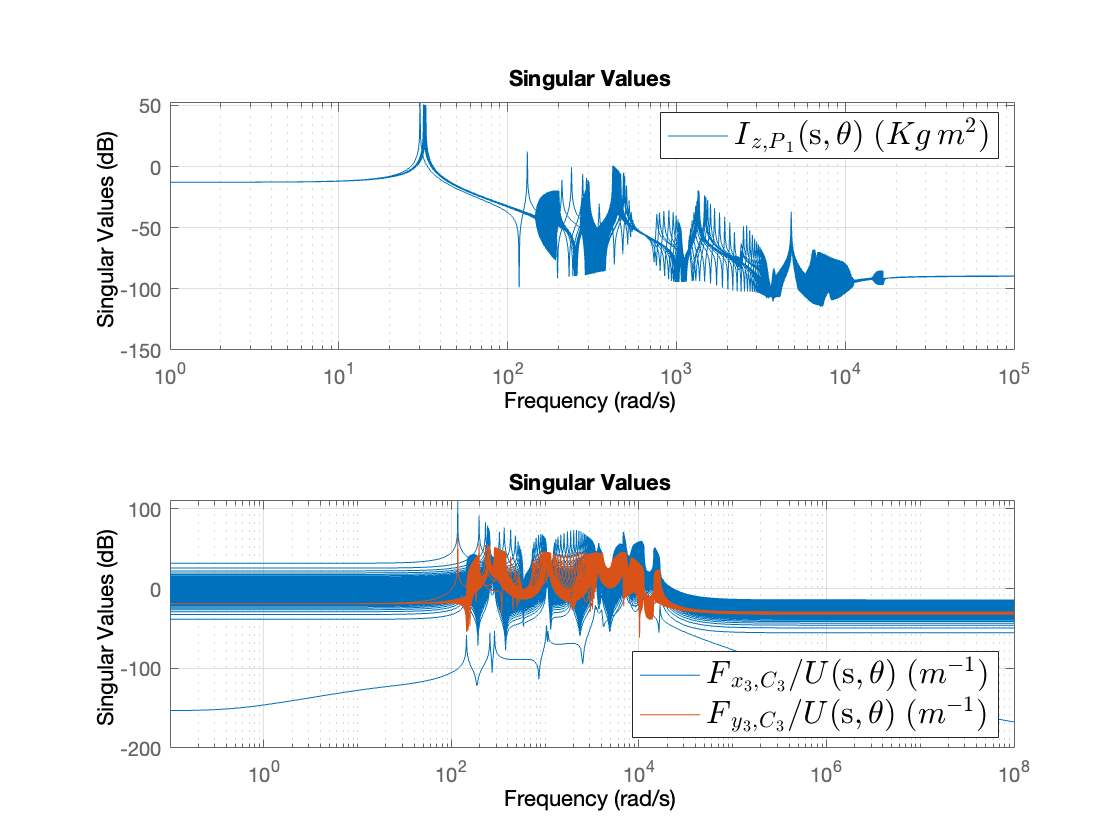

hold on
sigma(sysLPV(5,1,:))     % transfert from z-torque at P1 to Fy at C3
grid
legend('$F\_{x\_3,C\_3}/U(\mathrm s,\theta)\;(m^{-1})$',...
       '$F\_{y\_3,C\_3}/U(\mathrm s,\theta)\;(m^{-1})$',...
       'Interpreter','Latex','Fontsize',16,'Location','southeast')

Exactly as in the rigid case, the DCGAIN of $I_{z,P_1}(\mathrm s,\theta)$ does not depend on $\theta$.

One of the main interest of plotting the frequency-domain response of the system using its gain-scheduled representation `sysLPV` instead of its uncertain state-space reprentation `Gu` is that it is possible to click on a particular response in the graphic window to read the corresponding parametric configuration. For instance, in the botton figure, a response of the SISO transfer $F_{x_3,C_3}/U(\mathrm s,\theta)$ has a magnitude largely lower than the others: it corresponds to the configuration $\theta=\pi/2$. Indeed, for this configuration the axial force in the link 3 is null.

## 4. The rigid 4 bar mechanism free in 3D-space

Now the link # 0 is no more the inertial frame (ground) but a real beam and we consider in addition the $6\times 6$ dynamic model between an external wrench $\mathbf W_{./\mathcal L_0,C_0}$ applied to the mechanisim at the point $C_0$ and the acceleration twist $\ddot\mathbf x_{C_0}$ at this point. A new frame $\mathcal R_0$ attached to the link # 0 at the point $P_0$  is introduced:

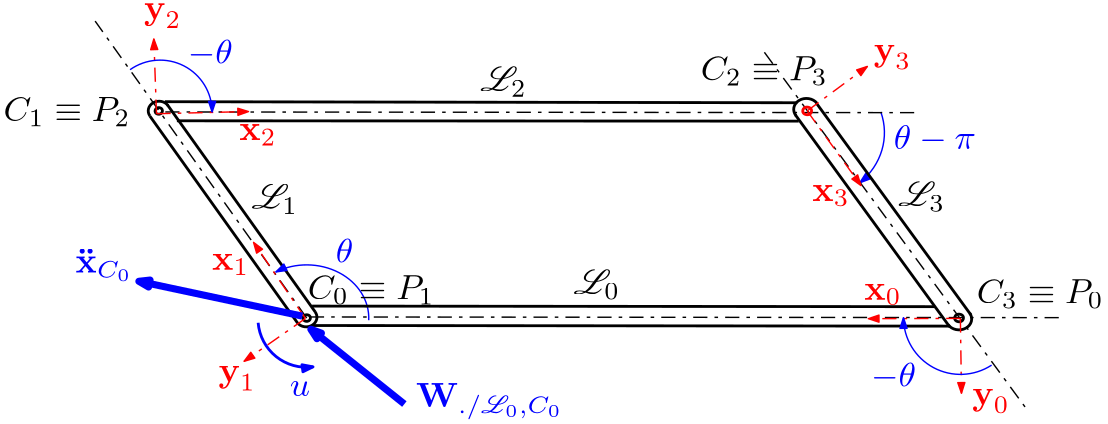

For the link # 0, the rigid body and the revolute joint (at point $C_3\equiv P_0$ ) are dissociated in the SIMULINK model in order to model the loop closure constraints. Furthermore, these constraints cannot be modeled using a "great" mass as it was proposed in section 2 since the model is now free to move in 3D-space. It is thus recommended to use a local spring-damper system acting on the relative motion between points $C_3$ and $P_0$ and only on the d.o.fs which required to be closed, here the $2$ translations in the $(\mathbf x,\;\mathbf z)$-plane.  

In the general case of  loop  closure constraints acting on the 6 d.o.fs, one can also use the block `Local Spring-Samper system` from the `6 dof mechanisms` sub-library. See also:

web Doc_6DOFs_spring_damper.html -new

Finally the SIMULINK model `FourRigidBarsFreeAug.slx` is displayed in the following Figure with the detailled of the sub-system: `Loop closure constraints at C3`.

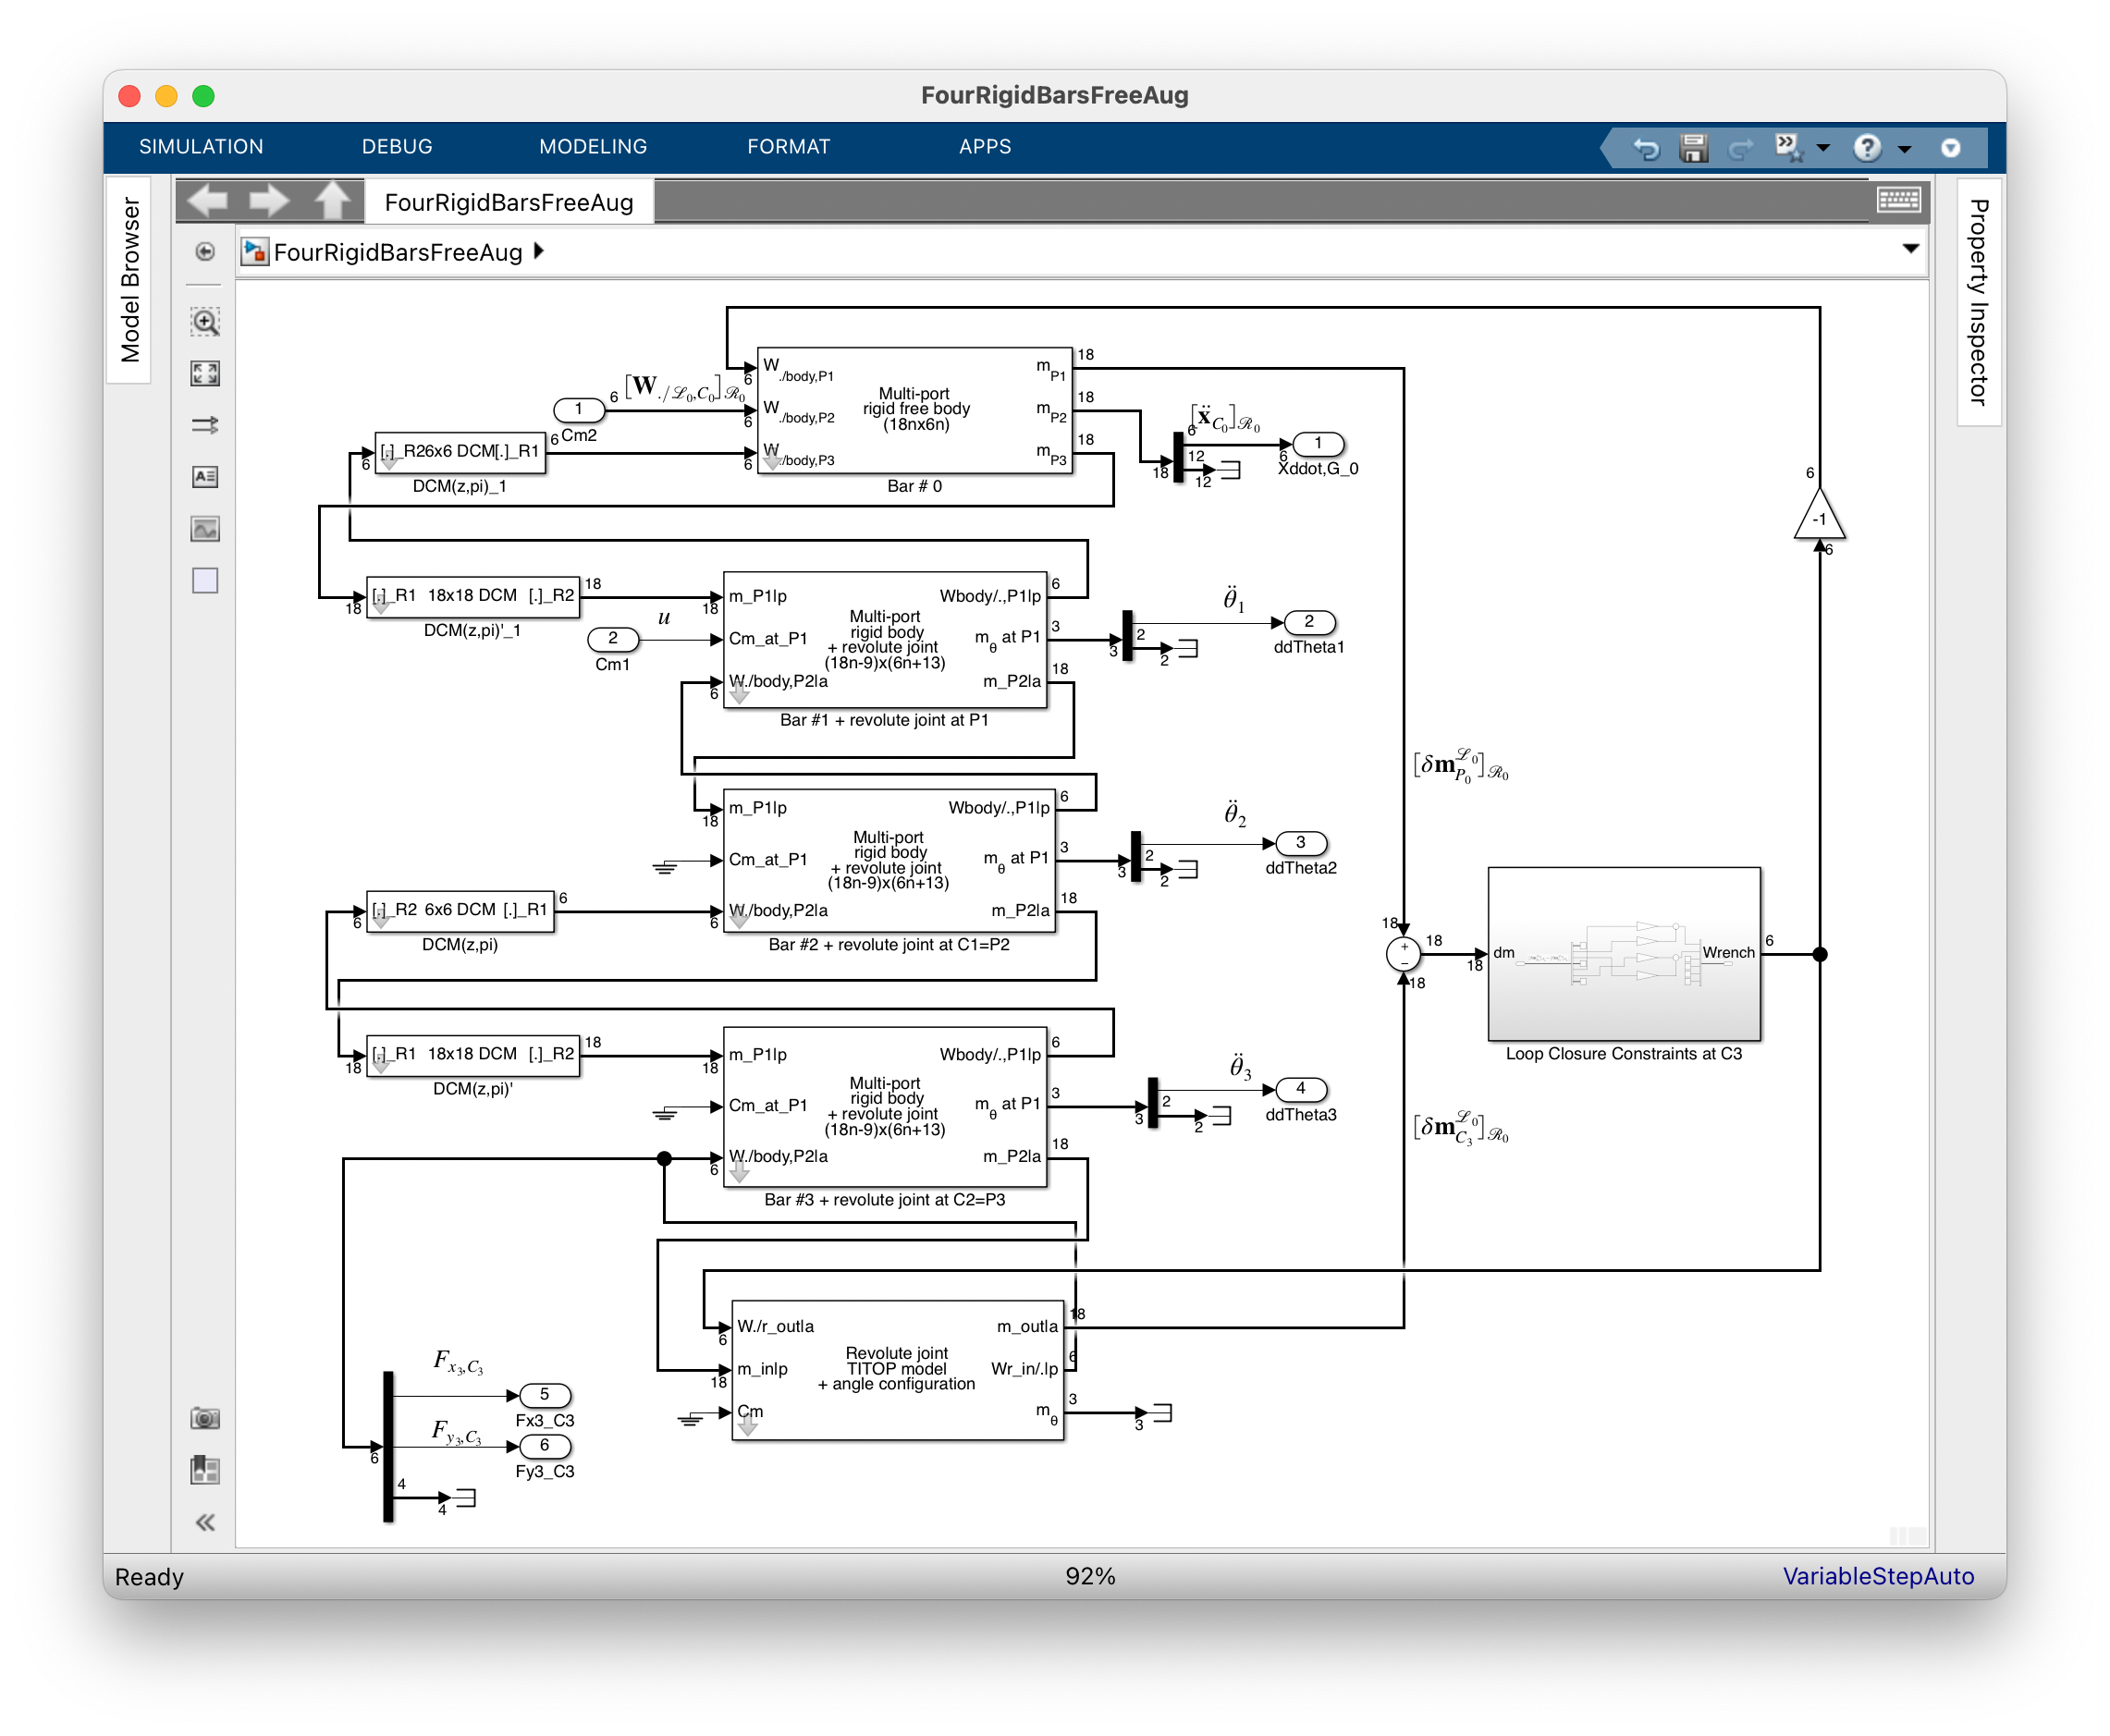

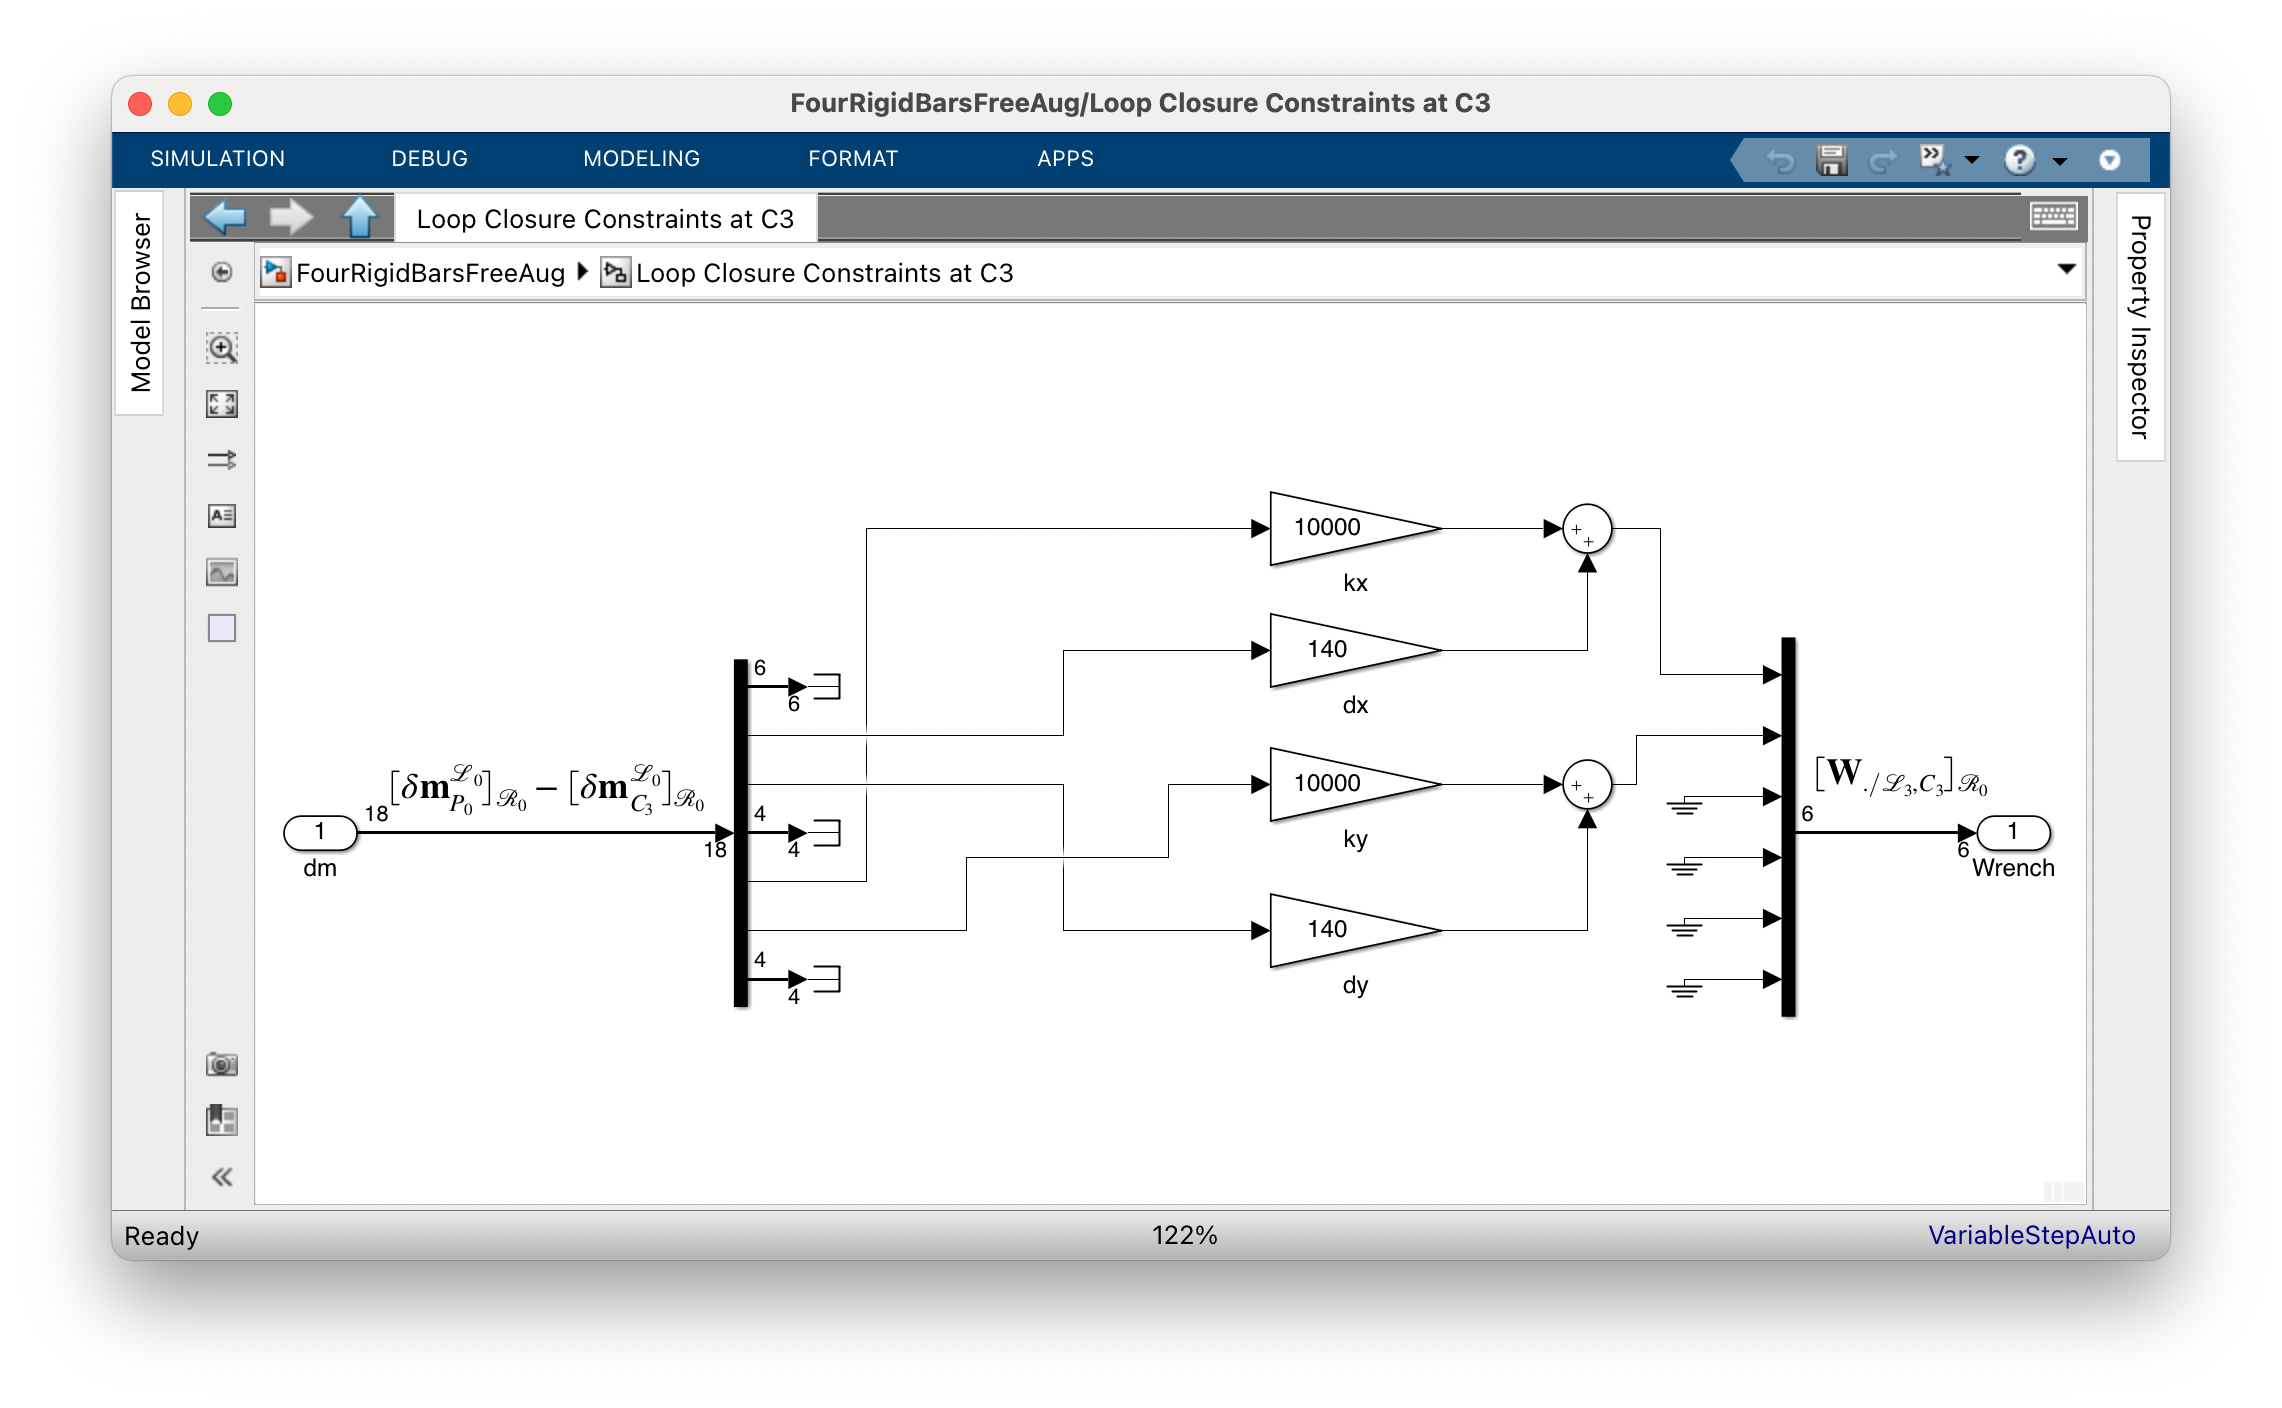

A stiffness of $10000\,N/m$ and a damping of $140\,Ns/m$ are arbitrary chosen for the spring and the damper on both $\mathbf x_0$ and $\mathbf y_0$axes. The only recommendation is to choose sufficiently high values in order to track the corresponding eigenvalues in the whole system dynamics once the model is computed, as it is ilustrated below.

The data relative to the link # 0 and the whole model in the configuration $\theta=\pi/4$:

l0=l2;
m0=rho*l0*h^2;
I0_G=diag([m0*h^2/6 m0/12*(h^2+l2^2) m0/12*(h^2+l2^2)]);

8 states removed.


Theta=pi/4;

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
 -7.30e+01     1.00e+00       7.30e+01         1.37e-02    
 -7.56e+01     1.00e+00       7.56e+01         1.32e-02    
 -1.31e+03     1.00e+00       1.31e+03         7.64e-04    
 -3.36e+03     1.00e+00       3.36e+03         2.98e-04    


FourRigidBarsFreeAug
G=linearize('FourRigidBarsFreeAug');
G=minreal(G);
damp(G)

The model `G` is a $4$-th order model between:

- 7 inputs: the 6 components of $[\mathbf W_{./\mathcal L_0,C_0}]_{\mathcal R_0}$ and $u$,

- $11$ outputs: the 6 components of  $[\mathbf{x''}^{\mathcal L_0}_{C_0}]_{\mathcal R_0}$, $\ddot \theta_1$, $\ddot\theta_2$, $\ddot\theta_3$, $F_{x_3,C_3}$ and  $F_{y_3,C_3}$ 

Due to the feedback loops in the SIMULINK model, the 4 integrators introduced for the loop closure constraints are moved far in the left-hand side of the complex plane.  These poles can be reduced considering the DCgain (low frequency behavior) of the system` G`:

G0=dcgain(G);

Then one can compute the $6\times 6$ apparent mass matrix  of the system seen from the point $P_0$ and projected in the frame $\mathcal R_0$:

- when the angular configuration of the parrallelogram is free to change:  one can check that the apparent mass is diffrent according to the 3 translations:

% Apparent 6x6 mass when the joint #1 is free

ans =
 
  D = 
            u1       u2       u3       u4       u5       u6
   y1   0.6694   0.2756        0        0        0  -0.1378
   y2   0.2756   0.6694        0        0        0  -0.3347
   y3        0        0    0.945  -0.2506   0.7231        0
   y4        0        0  -0.2506   0.1139  -0.2392        0
   y5        0        0   0.7231  -0.2392    0.747        0
   y6  -0.1378  -0.3347        0        0        0   0.3136
 
Static gain.



G0m1free=invio(ss(G0),1:6);
G0m1free(1:6,1:6)

- when the parrallelogram is locked in the angular configuration $\theta=\pi/4$. The apparent mass is the same for the 3 translations and equal to the total mass of the system $\Sigma_{i=1}^4\;m_i$:

% Apparent 6x6 mass when the joint #1 is locked at theta
G0m1lock=invio(ss(G0),1:7);

ans =
 
  D = 
               u1          u2          u3          u4          u5
   y1       0.945   2.195e-13           0           0           0
   y2  -2.747e-12       0.945           0           0           0
   y3           0           0       0.945     -0.2506      0.7231
   y4           0           0     -0.2506      0.1139     -0.2392
   y5           0           0      0.7231     -0.2392       0.747
   y6      0.2506     -0.7231           0           0           0
 
               u6
   y1      0.2506
   y2     -0.7231
   y3           0
   y4           0
   y5           0
   y6      0.8609
 
Static gain.



G0m1lock(1:6,1:6)

ans = 0.9450

m0+m1+m2+m3

One can also recover the result obtained in section 2 just by nulling the first 6 inputs ($[\ddot\mathbf x_{C_0}]_{\mathcal R_0}$) of the inverse model `G0m1free, `i.e.: the link # 0 is clamped on the inertial frame:

% Recovering the result of section 1
G0m1free(7:11,7)

ans =
 
  D = 
            u1
   y1     4.39
   y2     4.39
   y3     4.39
   y4  -0.6667
   y5  -0.1111
 
Static gain.



## 5. The flexible 4 bar mechanism free in 3D-space

In the case the 4 bars are flexible, the SIMULINK model is very simple and composed of:

- 4 bocks `TITOP flexible beam + revolute joint` blocs associated to the 4 links. **Note that only the acceleration dual vector (the first **$6$** components of the motion vector) are used in the interconnections of the various subsystems to close the kinematic chain,**

- some DCMs associated to the rotation of $\pm \pi$ around $\mathbf z$-axis, required to specify the vayring angular configuration $\theta$ as an` ureal `in the revolute joint dialog boxes (for numerical values of $\theta$ these DCM can be removed).

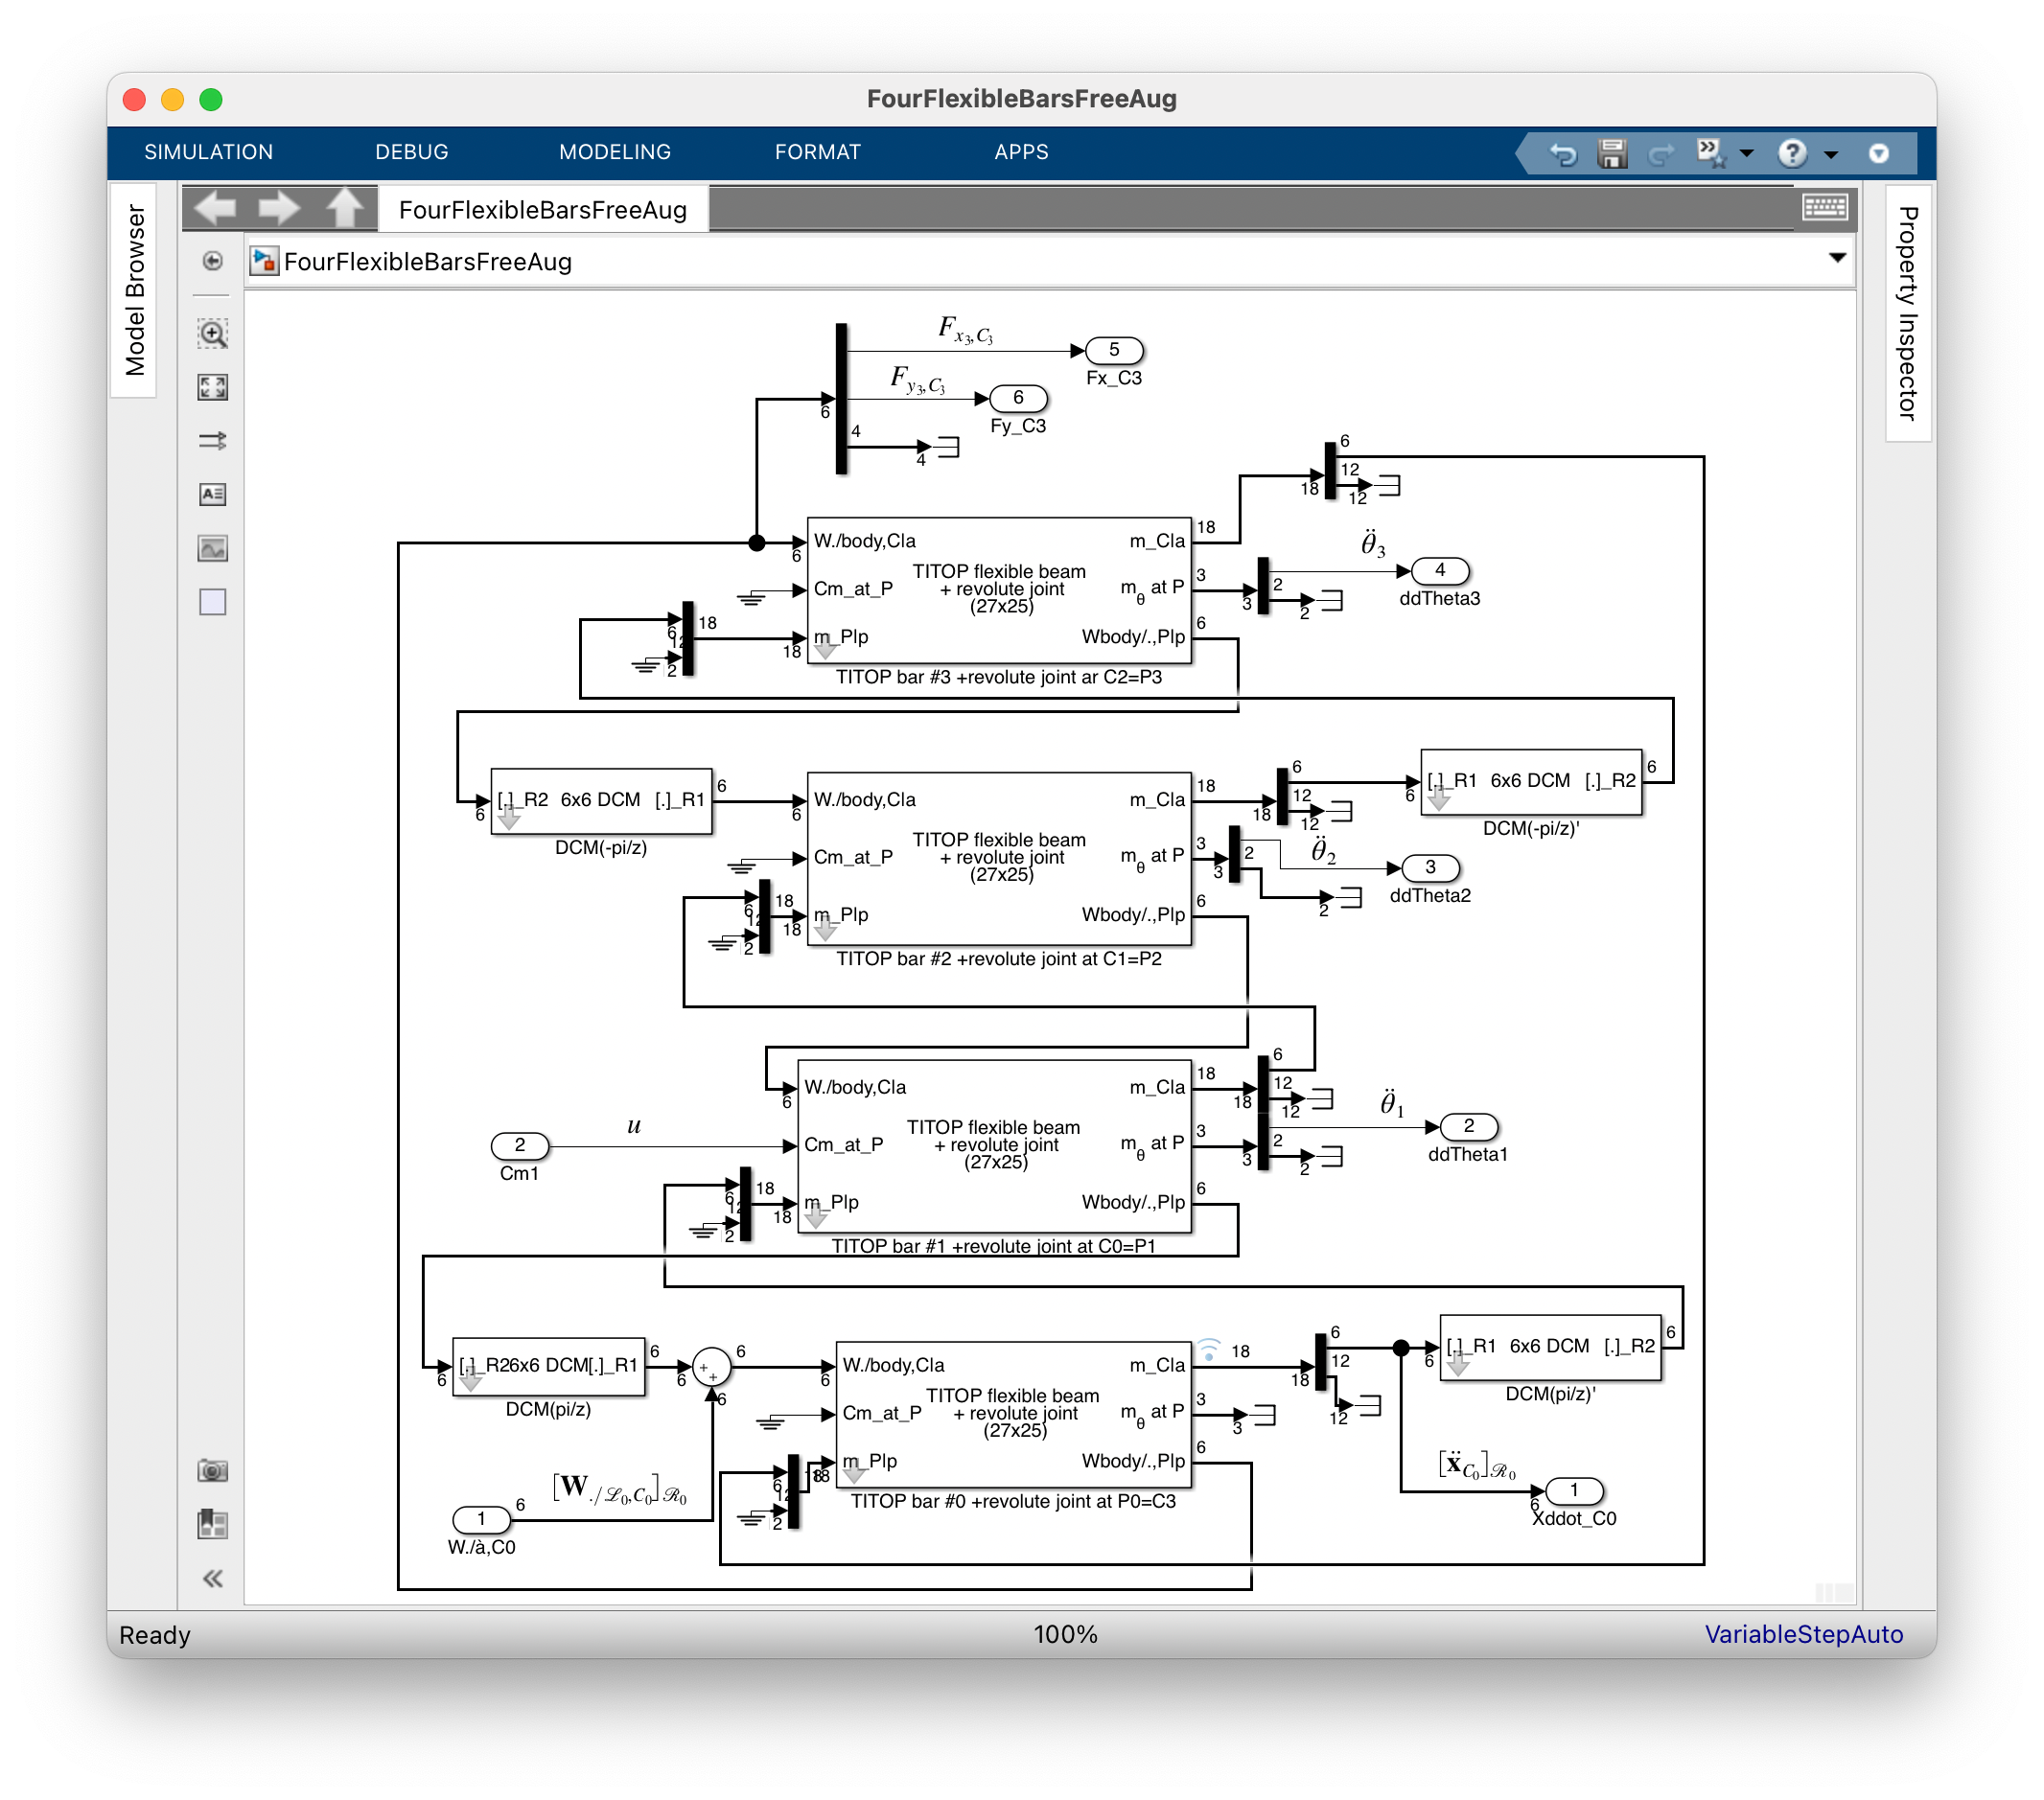

Considering the angular configuration $\theta=\pi/4$:

% Flexible case: free case
Theta=pi/4;
FourFlexibleBarsFreeAug
G=linearize('FourFlexibleBarsFreeAug');
damp(G)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -2.00e-13 + 4.83e-05i     4.14e-09       4.83e-05         4.99e+12    
 -2.00e-13 - 4.83e-05i     4.14e-09       4.83e-05         4.99e+12    
 -7.17e-05                 1.00e+00       7.17e-05         1.39e+04    
  7.17e-05                -1.00e+00       7.17e-05        -1.39e+04    
  9.16e-05                -1.00e+00       9.16e-05        -1.09e+04    
 -9.16e-05                 1.00e+00       9.16e-05         1.09e+04    
 -8.65e-02 + 1.04e+02i     8.35e-04       1.04e+02         1.16e+01    
 -8.65e-02 - 1.04e+02i     8.35e-04       1.04e+02         1.16e+01    
 -3.13e-01 + 1.76e+02i     1.77e-03       1.76e+02         3.19e+00    
 -3.13e-01 - 1.76e+02i     1.77e-03       1.76e+02         3.19e

The whole $11\times 7$ model G is a 80-th order system with $6$ poles around $0$ due to the internal constraints required to meet the loop closure contraints.

Note that in that case the` linearize` function fails to remove these modes. They can be removed using the function `minreal` but the out-of-$(\mathbf x,\;\mathbf y)$-plane flexible modes  are not reduced because they are controllable by $\mathbf W_{./\mathcal L_0,C_0}$and obdservable by  $[\mathbf{x''}^{\mathcal L_0}_{C_0}]_{\mathcal R_0}$.

Gr=minreal(G);

6 states removed.


One can recover the apparent $6\times 6$ apparent (rigid) mass matrix  of the system seen from the point $P_0$ and projected in the frame $\mathcal R_0$:

- when the angular configuration of the parrallelogram is free to change:  one can check that the apparent mass is diffrent according to the 3 translations:

Gm1free=invio(Gr,1:6);
dcgain(Gm1free(1:6,1:6))

ans =     0.6694    0.2756    0.0000   -0.0000    0.0000   -0.1378
    0.2756    0.6694    0.0000   -0.0000    0.0000   -0.3347
    0.0000    0.0000    0.9450   -0.2506    0.7231   -0.0000
   -0.0000   -0.0000   -0.2506    0.1139   -0.2392    0.0000
    0.0000    0.0000    0.7231   -0.2392    0.7470   -0.0000
   -0.1378   -0.3347   -0.0000    0.0000   -0.0000    0.3136


- when the parrallelogram is locked in the angular configuration $\theta=\pi/4$. The apparent mass is the same for the 3 translations and equal to the total mass of the system $\Sigma_{i=1}^4\;m_i$:

G0m1lock=invio(Gr,1:7);
dcgain(G0m1lock(1:6,1:6))

ans =     0.9450   -0.0000   -0.0000   -0.0000   -0.0000    0.2506
    0.0000    0.9450    0.0000   -0.0000    0.0000   -0.7231
   -0.0000    0.0000    0.9450   -0.2506    0.7231   -0.0000
    0.0000   -0.0000   -0.2506    0.1139   -0.2392    0.0000
   -0.0000    0.0000    0.7231   -0.2392    0.7470   -0.0000
    0.2506   -0.7231   -0.0000    0.0000   -0.0000    0.8609


The following sequence considers $\theta$ as a varying parameter and plots the frequency-domain responses of the apparent inertia $I_{z,P_1}(\mathrm s,\theta)$  and the gains between $u$ and the 2 outputs $F_{x_3,C_3}$, $F_{y_3,C_3} \,(m^{-1})$ as functions of $\theta$, when the link # 0 is clamped on the inertial frame at the point $C_0$. Note that the responses are different than the ones obtained in section 3 because, although the link  # 0  is clamped at point $C_0$, it is flexible.

Theta=ureal('theta',pi/2,'Range',[0 pi]);
Gu=ulinearize('FourFlexibleBarsFreeAug');
Gu=simplify(Gu,'full');
% Clamping the bar # 0 at C0=P1:
Gu0m1=invio(Gu,1:6);
theta=[1:1:179]*pi/180;
% Analysis:
clear sysLPV
for ii = 1:length(theta),
    sig4=tan(theta(ii)/4);
    sysLPV(:,:,ii) = minreal(usubs(Gu0m1(7:11,7),'tan_theta_div4',sig4));
end

40 states removed.
40 states removed.
40 states removed.
40 states removed.
40 states removed.
40 states removed.
40 states removed.
40 states removed.
40 states removed.
40 states removed.
40 states removed.
40 states removed.
40 states removed.
40 states removed.
40 states removed.
40 states removed.
40 states removed.
40 states removed.
40 states removed.
40 states removed.
40 states removed.
40 states removed.
40 states removed.
40 states removed.
40 states removed.
40 states removed.
40 states removed.
40 states removed.
40 states removed.
40 states removed.
40 states removed.
40 states removed.
40 states removed.
40 states removed.
40 states removed.
40 states removed.
40 states removed.
40 states removed.
40 states removed.
40 states removed.
40 states removed.
40 states removed.
40 states removed.
40 states removed.
40 states removed.
40 states removed.
40 states removed.
40 states removed.
40 states removed.
40 states removed.
40 states removed.
40 states removed.
40 states re

sysLPV.SamplingGrid = struct('Crank_configuration',theta);
figure
subplot(2,1,1)
sigma(1/sysLPV(1,1,:))   % Apparent inertia at point P_1
grid
legend('$I\_{z,P\_1}(\mathrm s,\theta)\;(Kg\,m^2)$','Interpreter',...
       'Latex','Fontsize',16)
subplot(2,1,2)
sigma(sysLPV(4,1,:))     % transfert from z-torque at P1 to Fx at C3

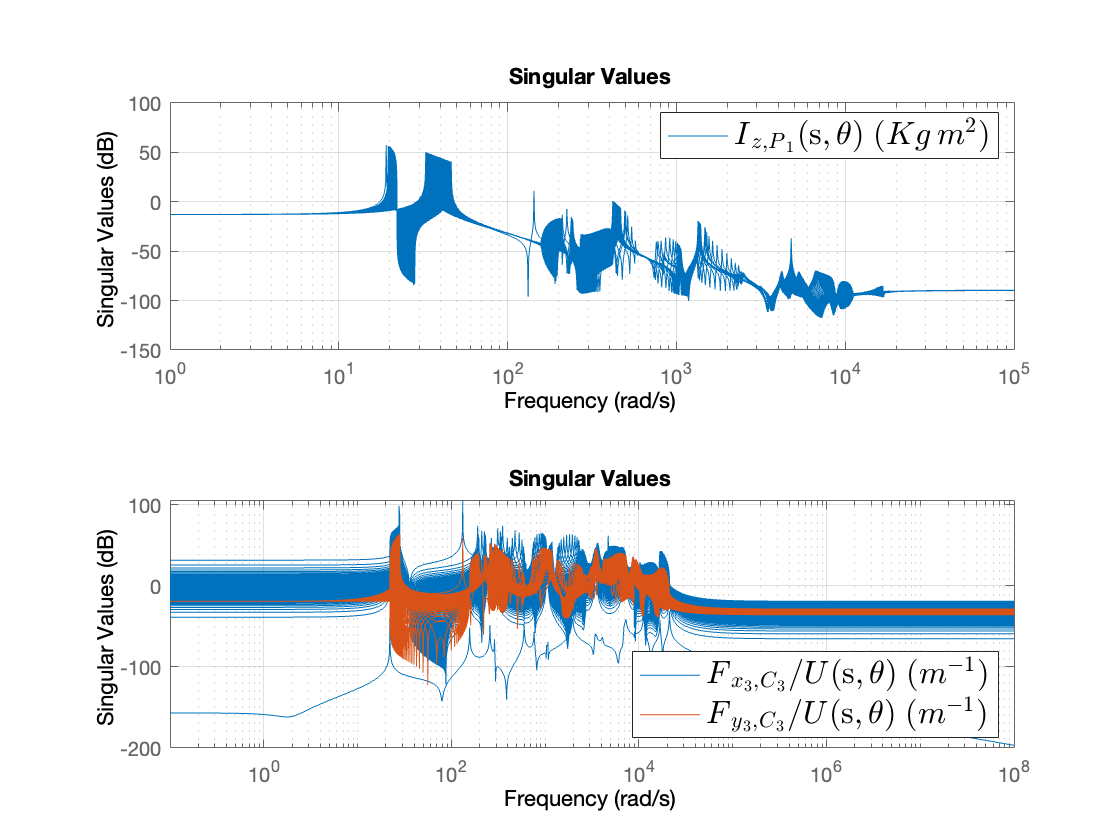

hold on
sigma(sysLPV(5,1,:))     % transfert from z-torque at P1 to Fy at C3
grid
legend('$F\_{x\_3,C\_3}/U(\mathrm s,\theta)\;(m^{-1})$',...
       '$F\_{y\_3,C\_3}/U(\mathrm s,\theta)\;(m^{-1})$',...
       'Interpreter','Latex','Fontsize',16,'Location','southeast')

## 6. References

- Chebbi, Jawhar and Dubanchet, Vincent and Perez Gonzalez, José Alvaro and Alazard, Daniel.  [*Linear dynamics of flexible multibody systems : a system-based approach.*](https://oatao.univ-toulouse.fr/16559/)     (2017) Multibody System Dynamics, 41 (1).  75-100. ISSN 1384-5640 